# Comparing Different methods of computing a Spherical Mean

As sphere is a manifold, not a vector space, how to compute a mean or a weighted mean on manifold is not clear. Some general methods

- Embed the manifold in extrior Euclidean space, compute mean in the vector space, and then project it back 

- Do a local coordinate chart on the manifold, do weighted averaging on the coordinates, and find the corresponding point on manifold. 

This is an important characteristic since 

addpath geomtry_util

### ZOHA Sphere 

In this block I' simulating the recombination process of ZOHA Sphere, and analyze it in geometrical term. 

%% Pure noise score
% score_fun = @(x) randn(size(x,1),1);
dimen = 4096; pop_size = 40;
weights = rankweight(40, 20);
basis_norm = 300;
mu_deg = 35;
lr = 1;
mu = mu_deg / 180 * pi / sqrt(dimen)

mu = 0.0095

%mu = 0.04;
basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 
ExpectStepSize = sqrt(dimen * sum(weights.^2)) * mu;
disp(ExpectStepSize)

    0.1816



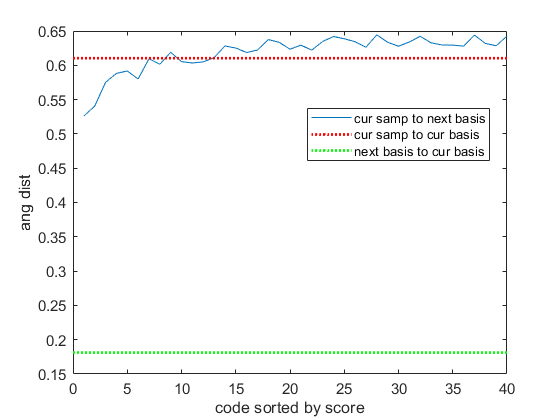

% gradnorm_ctr=zeros(1,10000);
% for i = 1:10000
tang_codes = mu * randn(pop_size, dimen);
f_basis = randn();%score_fun(basis_vec);
f_exp = randn(pop_size,1);%score_fun(basis_vec + tang_codes);
[sorted_f, sort_arg] = sort(f_exp);
hagrad = weights * tang_codes(sort_arg, :);
cur_codes = ExpMap(basis_vec, tang_codes);
next_basis = ExpMap(basis_vec, lr * hagrad);
cur_basis_samp = ang_dist(cur_codes, basis_vec);
nxt_angs = ang_dist(cur_codes, next_basis);
step_ang = ang_dist(basis_vec, next_basis);
%gradnorm_ctr(i) = norm(hagrad);
% end
figure, clf, plot(nxt_angs(sort_arg));%ylim([0,1.5])
hL = fig_horzline(mean(cur_basis_samp),axis);set(hL,"color","red")
hL = fig_horzline(step_ang,axis);set(hL,"color","green")
legend(["cur samp to next basis", "cur samp to cur basis", "next basis to cur basis"],"Location","best")
%fprintf("Pure Noise Score\tMean norm of grad %.3f, std %.3f", mean(gradnorm_ctr), std(gradnorm_ctr))
ylabel("ang dist");xlabel("code sorted by score")

### ZOHA Sphere Euclid Mean

In this block I' simulating the recombination process of ZOHA Sphere, and analyze it in geometrical term. 

%% Pure noise score
% score_fun = @(x) randn(size(x,1),1);
dimen = 4096; pop_size = 40;
weights = rankweight(40, 20);
basis_norm = 300;
mu_deg = 35;
lr = 1;
mu = mu_deg / 180 * pi / sqrt(dimen)

mu = 0.0095

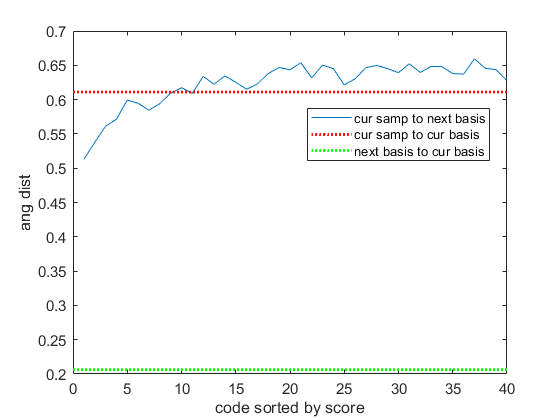

%mu = 0.04;
basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 
ExpectStepSize = sqrt(dimen * sum(weights.^2)) * mu;
%disp(ExpectStepSize)
% gradnorm_ctr=zeros(1,10000);
% for i = 1:10000
tang_codes = mu * randn(pop_size, dimen);
f_basis = randn();%score_fun(basis_vec);
f_exp = randn(pop_size,1);%score_fun(basis_vec + tang_codes);
[sorted_f, sort_arg] = sort(f_exp);
% hagrad = weights * tang_codes(sort_arg, :);
cur_codes = ExpMap(basis_vec, tang_codes);
next_basis = weights * cur_codes(sort_arg, :);
% next_basis = ExpMap(basis_vec, lr * hagrad);
cur_basis_samp = ang_dist(cur_codes, basis_vec);
nxt_angs = ang_dist(cur_codes, next_basis);
step_ang = ang_dist(basis_vec, next_basis);
%gradnorm_ctr(i) = norm(hagrad);
% end
figure, clf, plot(nxt_angs(sort_arg));%ylim([0,1.5])
hL = fig_horzline(mean(cur_basis_samp),axis);set(hL,"color","red")
hL = fig_horzline(step_ang,axis);set(hL,"color","green")
legend(["cur samp to next basis", "cur samp to cur basis", "next basis to cur basis"],"Location","best")
%fprintf("Pure Noise Score\tMean norm of grad %.3f, std %.3f", mean(gradnorm_ctr), std(gradnorm_ctr))
ylabel("ang dist");xlabel("code sorted by score")

### CMAES 

In this block I' simulating the recombination process of CMAES,  and analyze it in geometrical term. 

CMAES use the weighted vector mean in the 4096d code space! 

%% Pure noise score
% score_fun = @(x) randn(size(x,1),1);
dimen = 4096; pop_size = 40;
weights = rankweight(40, 20);
basis_norm = 250;
mu = 2.8;
basis_vec = zeros(1, dimen);
basis_vec(1) = basis_norm; 
ExpectStepSize = sqrt(dimen * sum(weights.^2)) * mu;
disp(ExpectStepSize)

   53.2864



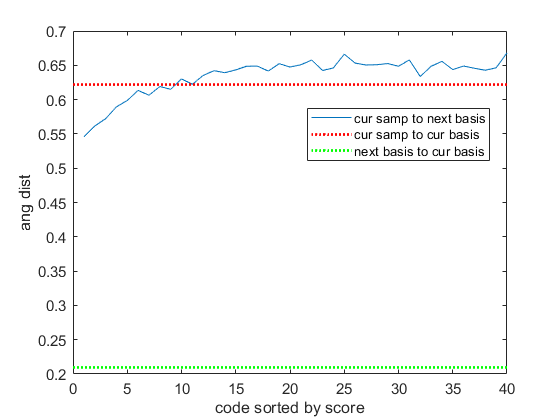

% gradnorm_ctr=zeros(1,10000);
% for i = 1:10000
tang_codes = mu * randn(pop_size, dimen);
f_basis = randn();%score_fun(basis_vec);
f_exp = randn(pop_size,1);%score_fun(basis_vec + tang_codes);
[sorted_f, sort_arg] = sort(f_exp);
hagrad = weights * tang_codes(sort_arg, :);
cur_codes = basis_vec + tang_codes;
next_basis = basis_vec + hagrad;
cur_basis_samp = ang_dist(cur_codes, basis_vec);
nxt_angs = ang_dist(cur_codes, next_basis);
step_ang = ang_dist(basis_vec, next_basis);
%gradnorm_ctr(i) = norm(hagrad);
% end
figure, clf, plot(nxt_angs(sort_arg));
hL = fig_horzline(mean(cur_basis_samp),axis);set(hL,"color","red")
hL = fig_horzline(step_ang,axis);set(hL,"color","green")
legend(["cur samp to next basis", "cur samp to cur basis", "next basis to cur basis"],"Location","best")
ylabel("ang dist");xlabel("code sorted by score")

sum(weights)

ans = 1.0000

ang_dist(basis_vec, next_basis)

ans = 0.1574